## **Introduction to the fuel cycle model**

This notebook will guide you through the basics of fuel cycle modeling. 

First, we will develop an analytical model for a simplified version of the fuel cycle. Then, we will simulate the simplified version of the fuel cycle in Simulink. We will compare the analytical solution with the simulink solution to verify the model. Finally, we will run a simulation of ARC fuel cycle with dummy parameters to assess the accuracy of the model.

Note: the **symbolic math toolbox is required**. 

### Simplified fuel cycle design

In this simplified model we consider just three blocks: the inner fuel cycle (IFC), the outer fuel cycle (OFC), and the storage system. The layout of the fuel cycle is shown in Figure 1.

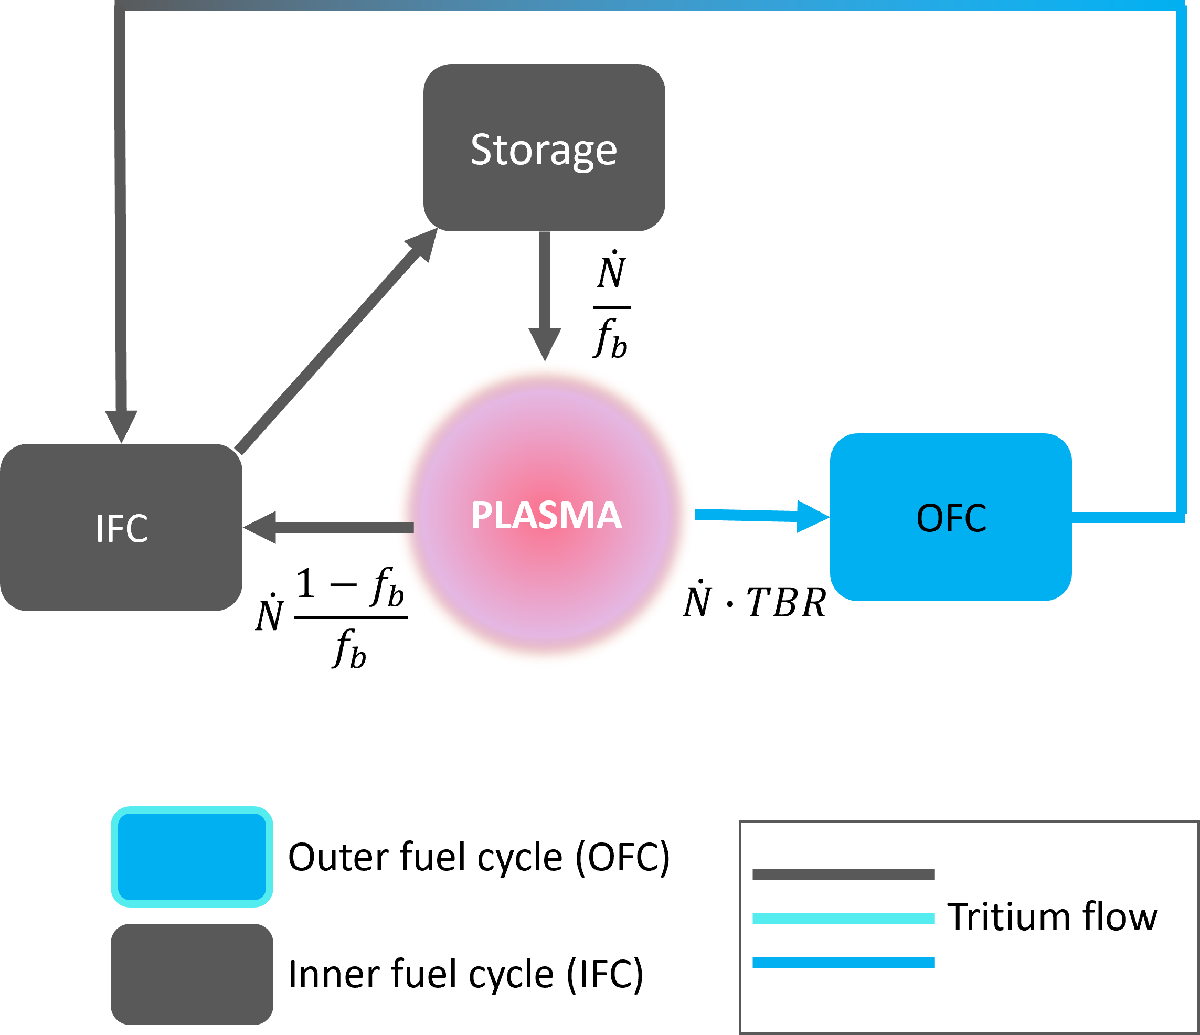

Figure 1 - Simplified fuel cycle layout.

The system of ODE describing the system is:


$$\[
    \left\{
                \begin{array}{ll}
                  \frac{{\mathrm{dI}}_{\mathrm{ofc}}(t) }{\mathrm{dt}}=\dot{\;N} \;\mathrm{TBR}-\frac{I_{\mathrm{ofc}}(t) }{\tau_{\mathrm{ofc}\;} }\\
                  \frac{{\mathrm{dI}}_{\mathrm{ifc}}(t) }{\mathrm{dt}}=\frac{1-f_{b\;} }{f_{b\;} \;}\;\dot{\;N} +\frac{I_{\mathrm{ofc}}(t) }{{\tau \;}_{\mathrm{ofc}} }-\frac{I_{\mathrm{ifc}}(t) }{\tau {\;}_{\mathrm{ifc}} }\\
                  \frac{{\mathrm{dI}}_{\mathrm{st}} (t)}{\mathrm{dt}\;}=\frac{I_{\mathrm{ifc}}(t) }{\tau_{\mathrm{ifc}} }-\dot{\;\frac{N}{f_{b\;} }}
                \end{array}
              \right.
  \]$$


where $\dot{\;N}$ is the tritium burn rate, $f_b$ is the tritium burn fraction, $\tau {\;}_i$ is the residence time in component i and $I_{i\;}$ is the tritium inventory in component i. You can easily solve the system of equations analytically (it just takes some time) or symbolically in MATLAB. The initial condition for the IFC and the OFC inventories is $I_{\textrm{ifc}} \left(t=0\right)=I_{\textrm{ofc}} \left(t=0\right)=0$; i.e., the initial tritium inventory in the IFC and OFC is zero at the beginnig of operations. The initial inventory in the storage system is the start-up inventory, $I_{s,0}$. For the moment let's assume it is just a number, we will go deeper into this topic later.

clear all
syms I_ofc(t) % OFC tritium inventory
syms I_ifc(t) % IFC tritium inventory
syms I_st(t) % Storage inventory
syms t % time
syms N_dot
syms tau_ifc
syms tau_ofc
syms TBE
syms TBR
syms I_s_0

% ODE
ode_1 = diff(I_ofc,t) == N_dot * TBR - I_ofc/tau_ofc % OFC

$$ode\_1(t) = \frac{\partial }{\partial t}I_{\mathrm{ofc}}\left(t\right)=\dot{N}\,\mathrm{TBR}-\frac{I_{\mathrm{ofc}}\left(t\right)}{\tau_{\mathrm{ofc}}}$$

ode_2 = diff(I_ifc,t) == (1-TBE)/TBE * N_dot + I_ofc/tau_ofc - I_ifc/tau_ifc % IFC

$$ode\_2(t) = \frac{\partial }{\partial t}I_{\mathrm{ifc}}\left(t\right)=\frac{I_{\mathrm{ofc}}\left(t\right)}{\tau_{\mathrm{ofc}}}-\frac{I_{\mathrm{ifc}}\left(t\right)}{\tau_{\mathrm{ifc}}}-\frac{\dot{N}\,\left(\mathrm{TBE}-1\right)}{\mathrm{TBE}}$$

ode_3 = diff(I_st,t) == I_ifc/tau_ifc - N_dot/TBE % Storage

$$ode\_3(t) = \frac{\partial }{\partial t}I_{\mathrm{st}}\left(t\right)=\frac{I_{\mathrm{ifc}}\left(t\right)}{\tau_{\mathrm{ifc}}}-\frac{\dot{N}}{\mathrm{TBE}}$$

% Initial conditions
cond_1 = I_ofc(0) == 0;
cond_2 = I_ifc(0) == 0;
cond_3 = I_st(0) == I_s_0;

assume(t,'real') % assume that time is a real quantity - simplify the resolution of the ODE

sol_1 = dsolve(ode_1,cond_1)

$$sol\_1 = \dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}-\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}\,{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ofc}}}}$$

Now that we know the explicit solution for $I_{\textrm{ofc}} \left(t\right)$ we rewrite Eq. (2) by replacing the symbolic function $I_{\textrm{ofc}} \left(t\right)$ with its analytical expression (sol_1)

ode_2 = diff(I_ifc,t) == (1-TBE)/TBE * N_dot + sol_1/tau_ofc - I_ifc/tau_ifc % Note sol_1 replacing I_ofc

$$ode\_2(t) = \frac{\partial }{\partial t}I_{\mathrm{ifc}}\left(t\right)=\frac{\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}-\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}\,{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ofc}}}}}{\tau_{\mathrm{ofc}}}-\frac{I_{\mathrm{ifc}}\left(t\right)}{\tau_{\mathrm{ifc}}}-\frac{\dot{N}\,\left(\mathrm{TBE}-1\right)}{\mathrm{TBE}}$$

sol_2 = dsolve(ode_2,cond_2)

$$sol\_2 = {\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(\frac{\dot{N}\,\tau_{\mathrm{ifc}}\,{\mathrm{e}}^{t/\tau_{\mathrm{ifc}}}}{\mathrm{TBE}}-\tau_{\mathrm{ifc}}\,{\mathrm{e}}^{t/\tau_{\mathrm{ifc}}}\,\left(\dot{N}-\dot{N}\,\mathrm{TBR}\right)+\frac{\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}\,\tau_{\mathrm{ofc}}\,{\mathrm{e}}^{\frac{t}{\tau_{\mathrm{ifc}}}-\frac{t}{\tau_{\mathrm{ofc}}}}}{\tau_{\mathrm{ifc}}-\tau_{\mathrm{ofc}}}\right)-{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(\frac{\dot{N}\,\tau_{\mathrm{ifc}}}{\mathrm{TBE}}-\tau_{\mathrm{ifc}}\,\left(\dot{N}-\dot{N}\,\mathrm{TBR}\right)+\frac{\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}\,\tau_{\mathrm{ofc}}}{\tau_{\mathrm{ifc}}-\tau_{\mathrm{ofc}}}\right)$$

We now do the same for Eq. (3)

ode_3 = diff(I_st,t) == sol_2/tau_ifc - N_dot/TBE

$$ode\_3(t) = \frac{\partial }{\partial t}I_{\mathrm{st}}\left(t\right)=-\frac{\dot{N}}{\mathrm{TBE}}-\frac{{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(\frac{\dot{N}\,\tau_{\mathrm{ifc}}}{\mathrm{TBE}}-\tau_{\mathrm{ifc}}\,\left(\dot{N}-\dot{N}\,\mathrm{TBR}\right)+\frac{\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}\,\tau_{\mathrm{ofc}}}{\tau_{\mathrm{ifc}}-\tau_{\mathrm{ofc}}}\right)-{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(\frac{\dot{N}\,\tau_{\mathrm{ifc}}\,{\mathrm{e}}^{t/\tau_{\mathrm{ifc}}}}{\mathrm{TBE}}-\tau_{\mathrm{ifc}}\,{\mathrm{e}}^{t/\tau_{\mathrm{ifc}}}\,\left(\dot{N}-\dot{N}\,\mathrm{TBR}\right)+\frac{\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}\,\tau_{\mathrm{ofc}}\,{\mathrm{e}}^{\frac{t}{\tau_{\mathrm{ifc}}}-\frac{t}{\tau_{\mathrm{ofc}}}}}{\tau_{\mathrm{ifc}}-\tau_{\mathrm{ofc}}}\right)}{\tau_{\mathrm{ifc}}}$$

sol_3 = dsolve(ode_3,cond_3) 

$$sol\_3 = \frac{\tau_{\mathrm{ifc}}\,{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(\dot{N}\,\tau_{\mathrm{ifc}}-\dot{N}\,\tau_{\mathrm{ofc}}\right)}{\mathrm{TBE}\,\tau_{\mathrm{ifc}}-\mathrm{TBE}\,\tau_{\mathrm{ofc}}}-\frac{{\mathrm{e}}^{-\frac{t}{\tau_{\mathrm{ifc}}}}\,\left(t\,{\mathrm{e}}^{t/\tau_{\mathrm{ifc}}}\,\left(\dot{N}\,\tau_{\mathrm{ifc}}-\dot{N}\,\tau_{\mathrm{ofc}}-\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}+\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}\right)-\tau_{\mathrm{ifc}}\,\left(\dot{N}\,\tau_{\mathrm{ofc}}-\dot{N}\,\tau_{\mathrm{ifc}}+\dot{N}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}\right)+\dot{N}\,\mathrm{TBR}\,{\tau_{\mathrm{ofc}}}^{2}\,{\mathrm{e}}^{\frac{t}{\tau_{\mathrm{ifc}}}-\frac{t}{\tau_{\mathrm{ofc}}}}\right)}{\tau_{\mathrm{ifc}}-\tau_{\mathrm{ofc}}}-\frac{\dot{N}\,\tau_{\mathrm{ifc}}-I_{s,0}\,\mathrm{TBE}-\dot{N}\,\mathrm{TBE}\,\tau_{\mathrm{ifc}}+\dot{N}\,\mathrm{TBE}\,\mathrm{TBR}\,\tau_{\mathrm{ifc}}+\dot{N}\,\mathrm{TBE}\,\mathrm{TBR}\,\tau_{\mathrm{ofc}}}{\mathrm{TBE}}$$

You can solve the equations analytically to convince yourself that the solutions found by MATLAB are correct (MATLAB is not good at rearranging the terms, but the solutions are correct). Let's now use numerical parameters to compute the inventories.

% Solve the equations by plugging real FC parameters
clear ode_1 ode_2 ode_3 cond_1 cond_2 cond_3 sol_1 sol_2 sol_3 

% FC parameters
N_dot = 8.99e-7; % kg/s
tau_ifc = 3 * 3600; % s
tau_ofc = 24.3 * 3600; % s
TBE = 0.01; 
TBR = 1.08;
I_s_0 = 1.5; % kg

% OFC
ode_1 = diff(I_ofc,t) == N_dot * TBR - I_ofc/tau_ofc; % OFC
cond_1 = I_ofc(0) == 0;
sol_1 = dsolve(ode_1,cond_1);
% IFC
ode_2 = diff(I_ifc,t) == (1-TBE)/TBE * N_dot + sol_1/tau_ofc - I_ifc/tau_ifc; % IFC
cond_2 = I_ifc(0) == 0;
sol_2 = dsolve(ode_2,cond_2);
% Storage
ode_3 = diff(I_st,t) == sol_2/tau_ifc - N_dot/TBE; % Storage;
cond_3 = I_st(0) == I_s_0;
sol_3 = dsolve(ode_3,cond_3);

1If we plot the results we find a not-surprising $\left(1-\exp \left(-\frac{t}{\tau_{i\;} \;\;}\right)\right)$ trend for $I_{\textrm{ifc}}$ and $I_{\textrm{ofc}}$. Note that the transient in the IFC lasts much less because of the shorter residence time in the IFC. More interesting is the plot for $I_{\textrm{st}}$. The start-up inventory decreases down to a minimum, which is by chance > 0. Our mathematical model does not know anything about tritium self-sufficiency, so we would have found an acceptable (mathematically speaking) solution even if the start-up inventory had been lower and the minimum of the storage inventory had been < 0. Our goal when using the model in Simulink will be to find the minimum start-up inventory such tha $I_{\textrm{st}} \left(t\right)>0,\forall t$. A $I_{\textrm{st}} \left(t\right)<0$ means that there is no more tritium in the storage system, and the reactor cannot be fuelled. 

tt = [0 3600*24*10]; % time vector for plots - 10 days

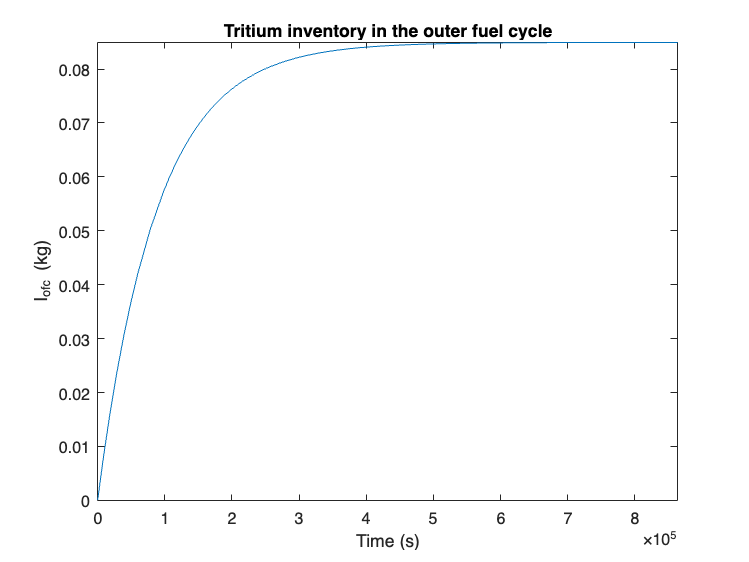

% OFC
figure(1)
fplot(sol_1,tt)
xlabel('Time (s)')
ylabel('I_{ofc} (kg)')
title('Tritium inventory in the outer fuel cycle')

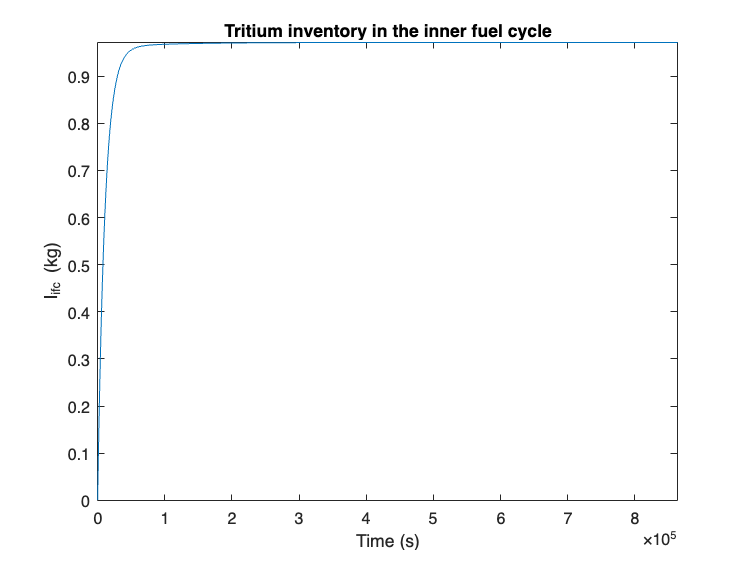

% IFC
figure(2)
fplot(sol_2,tt)
xlabel('Time (s)')
ylabel('I_{ifc} (kg)')
title('Tritium inventory in the inner fuel cycle')

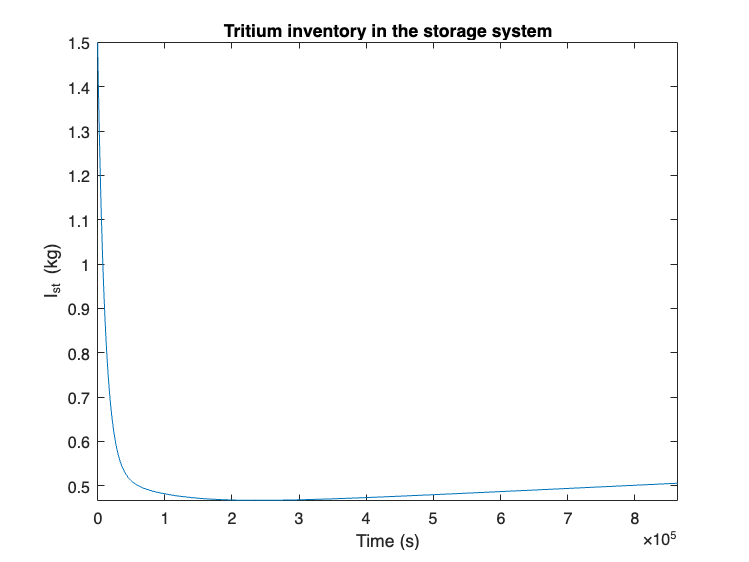

% Storage inventory
figure(3)
fplot(sol_3,tt)
xlabel('Time (s)')
ylabel('I_{st} (kg)')
title('Tritium inventory in the storage system')

Another quantity of interest for tritium self-sufficiency analysis is the inflection time (i.e., the time at which the storage inventory starts increasing). The inflection time is reached when the longer transient in the system is almost completed. Since the longer time scale in the system is $\tau {\;}_{\textrm{ofc}}$, we might expect the inflection time to be at $\sim 3\tau {\;}_{\textrm{ofc}} \sim 3\;\textrm{days}$. However,  the sum of the flows entering the storage system is higher than the flow exiting the system (otherwise we couldn't build-up a tritium inventory to start new plants). At steady state:


$$\dot{\;N} \;\textrm{TBR}+\dot{\;N} \frac{\left(1-f_b \right)}{f_{b\;} }-\frac{\dot{\;N} }{f_{b\;} }=\dot{\;N} \left(\textrm{TBR}-1\right)>0$$


This means that the inflection time is reached before the longest transient ends because the incoming tritium flows balance the tritium outflow sooner than $\sim 3\tau {\;}_{\textrm{ofc}}$. 

figure(1)
m_dot_ifc = sol_2 / tau_ifc

$$m\_dot\_ifc = -\frac{3\,{\mathrm{e}}^{-\frac{t}{10800}}\,\left(30949020442447623\,{\mathrm{e}}^{\frac{71\,t}{874800}}-2513875578160622033\,{\mathrm{e}}^{t/10800}+2482926557718174410\right)}{83822005070936202543104}$$

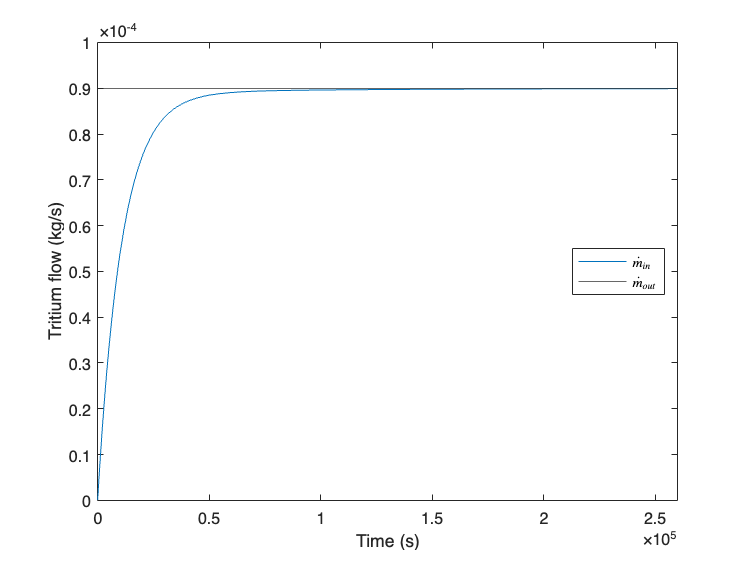

fplot(m_dot_ifc,[0 3600*24*3])
yline(N_dot/TBE)
ylim([0 1e-4])
legend('$\dot{m}_{in}$','$\dot{m}_{out}$','Interpreter','latex', 'Location','east')
xlabel('Time (s)')
ylabel('Tritium flow (kg/s)')

% Compute the time at which the two flows balances
time = tt(1):tt(end); % create a time array
sol_2_num = matlabFunction(sol_2); % convert the symbolic function to a Matlab function
idx = find(sol_2_num(time)/tau_ifc>N_dot/TBE,1); % find index at which the flow balances
fprintf("Time at which the flow balances: " + time(idx)/3600/24 + " days")

Time at which the flow balances: 2.7686 days


% Export the function
myfun = matlabFunction(m_dot_ifc);
header = {'time[s]','m_in'};
writecell(header,strcat('basic_fc_flow.csv'), "WriteMode","overwrite", 'Delimiter',','); % Use writecell because writematrix does not add the delimiter between strings 
writematrix([time(1:3*idx)',myfun(time(1:3*idx)')], strcat('basic_fc_flow.csv'), "WriteMode","append");

% Sanity check - we should get the same result by finding the time at which
% dI_St/dt = 0
g = diff(sol_3,t) == 0;
t_infl_analytic = vpasolve(g);
t_infl_analytic = double(t_infl_analytic/ 3600 / 24);
fprintf("Inflection time (analytical): " + t_infl_analytic + " days")

Inflection time (analytical): 2.7686 days

Let's get back to the start-up inventory. We assumed a start-up inventory of 1.5 kg, which is a fairly accurate value for these choice of reactor parameters. In a real-world scenario the start-up inventory is an unknown quantity. A good initial guess for the start-up inventory can be made according to the following argument. 

There are two flows entering the IFC, one coming from the OFC and the other from the plasma exhaust. At a first glance we might expect the start-up inventory to be equal to the tritium burned until the bred tritium becomes available. This would lead to a huge underestimation of the start-up inventory. 

t_burned = N_dot * tau_ofc; 
fprintf("Tritium burned during the initial OFC transient: " + t_burned + " kg")

Tritium burned during the initial OFC transient: 0.078645 kg

The amount of tritium burned is approximately 5% of the start-up inventory. At low burn fractions the OFC tritium flow rate is much lower than the tritium flow entering the IFC from the plasma exhaust:


$$\frac{\dot{N} \;\textrm{TBR}}{\dot{\;N} \frac{\left(1-f_b \right)}{f_{b\;} }}\;<<1$$


Therefore, the dominant term is the tritium flow entering the IFC from the plasma exhaust. The timescale associated to the processing of this flow is $\tau_{\textrm{ifc}}$, so we can compute the contribution of the $\dot{\;N} \frac{\left(1-f_b \right)}{f_{b\;} }$ flow to the start-up inventory:

t_from_exhaust = N_dot*(1-TBE)/TBE * tau_ifc; 
fprintf("Tritium not burned and flowing in the IFC \nduring the initial IFC transient: " + t_from_exhaust + " kg")

Tritium not burned and flowing in the IFC 
during the initial IFC transient: 0.96121 kg

fprintf("Total tritium to be supplied: " + (t_burned + t_from_exhaust) +  " kg")

Total tritium to be supplied: 1.0399 kg

An educated guess for the start-up inventory would be 1.05 kg. We can compare this value with the exact value computed analytically:


$$\int_0^{t_{\textrm{ifnl}\;} } {\dot{m} }_{\textrm{out},\textrm{storage}} -{\dot{m} }_{\textrm{in},\textrm{storage}} \;\textrm{dt}=\int_0^{t_{\inf } } \frac{\dot{N} }{f_{b\;} }-\frac{I_{\textrm{ifc}\;} }{\tau_{\textrm{ifc}\;} }\;\textrm{dt}$$


this is nothing but the solution of Eq. (3) with opposite sign:


$$\int_{t_{\textrm{infl}\;} }^0 \frac{I_{\textrm{ifc}\;} }{\tau_{\textrm{ifc}\;} }-\frac{\dot{N} }{f_{b\;} }\;\textrm{dt}=I_{\textrm{st}} \left(0\right)-I_{\textrm{st}\;} \left(t_{\inf } \right)$$


so we can compute it directly from the analytical solution.

sol_3_num = matlabFunction(sol_3); % convert the symbolic function to a Matlab function
fprintf("Start-up inventory = " + (sol_3_num(0) - sol_3_num(time(idx))) + " kg")

Start-up inventory = 1.0331 kg

The analytical value is quite close to out initial guess.

This approach works well for very simple cases in which the computational time is not an issue. The initial guess for the start-up inventory can be made as explained previously and the calculations can be iterated until we manage to minimize $I_{s,0}$. For  complex systems solving the equations analytically becomes impractical, so we need to develop more accurate computational models. Despite in a real systems there will be losses, inner loops, delays and other factors affecting the initial transient in the FC, the approximation for $I_{s,0}$ remains a usefull starting point.

Let's run the same model in Simulink and compare the solutions

out = sim("basic_FC.slx");
I_st = out.I_10;
[dummy, index ] = min(I_st);
t_infl_model = out.tout(index)/24/3600;
disp("Inflection time: " + t_infl_model + " days")

Inflection time: 2.7688 days


disp("Relative error between the computational model and the analytical model: " + (t_infl_model - t_infl_analytic)/t_infl_analytic*100 + "%")

Relative error between the computational model and the analytical model: 0.004267%


The relative error between the two solutions is just 0.004%. Since Simulink solves the same system of equations, but with a different approach, we expect an error close to (but different from) 0.

### **ARC fuel cycle model**

We are now running a more complex model with the following layout (Figure 2).

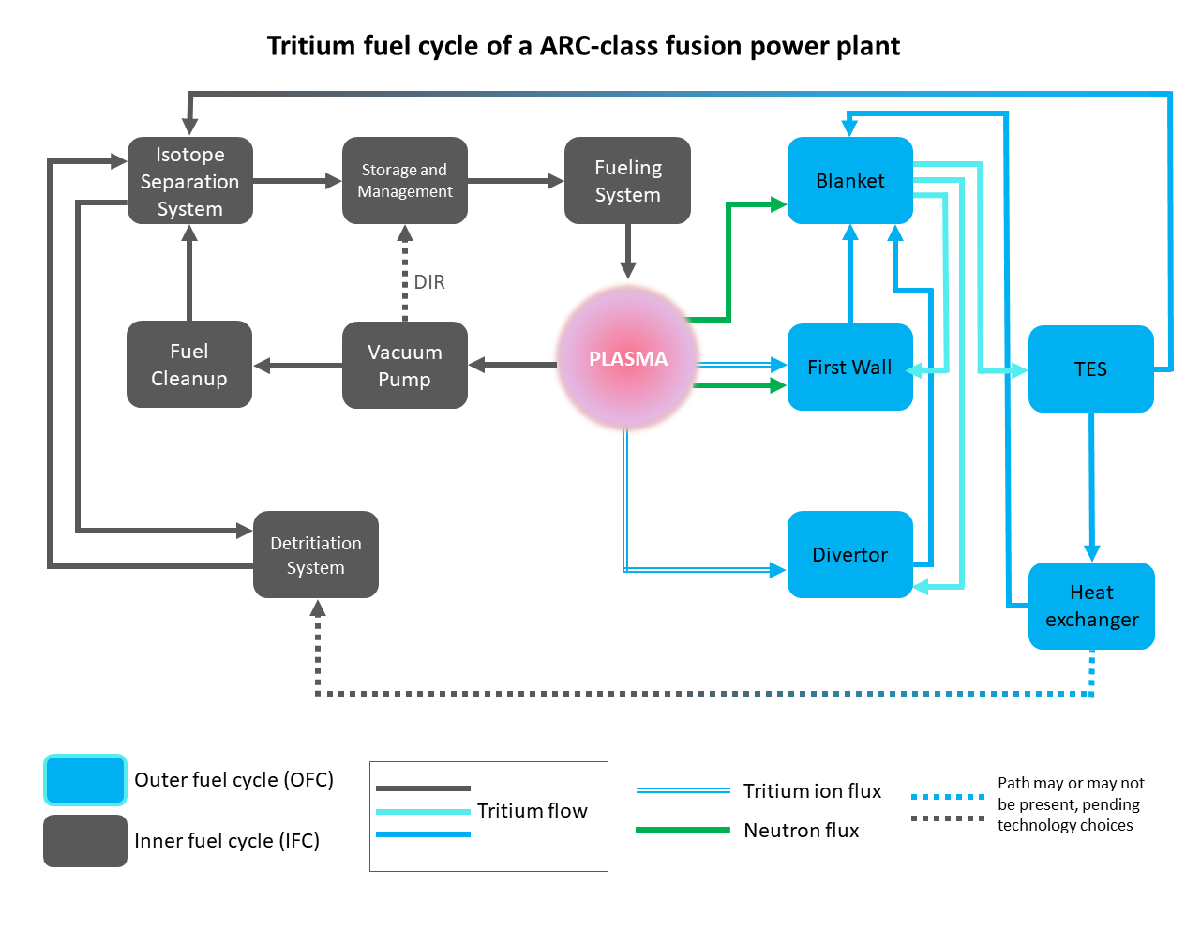

Figure 2 - Fuel cycle layout of a ARC-class FPP.

However, we will use some dummy parameters to make the IFC and OFC timescales similar to the ones used in the previous calculation. In this way we can compare the results from the more detailed model (which is a kind of black box) to the simpler, interpretable models we analysed previously.

% Residence times [s]
tau1 = 1*1200; % Blanket
tau2 = 1*24*3600; % TES
tau3 = 10; % FW
tau4 = 10; % Divertor
tau5 = 10; % HX
tau6 = 10; % Detritiation system
tau7 = 600; % Vacuum pump 
tau8 = 1*3600; % Fuel clean-up - tau8+tau9 = 4h from Abdou's paper
tau9 = 3*3600; % ISS -  tau8+tau9 = 4h from Abdou's paper
tau12 = 100; % Membrane separation

% tau10 = 1*3600;
tau10 = 0;
% Decay constant
lambda = 0;
% Non-radioactive losses fraction
epsi = 0;
% Effective residence time
T1 = 1/((1 + epsi)/tau1 + lambda); % Blanket
T2 = 1/((1 + epsi)/tau2 + lambda); % TES
T3 = 1/((1 + 0)/tau3 + lambda); % FW
T4 = 1/((1 + 0)/tau4 + lambda); % Divertor
T5 = 1/((1 + epsi)/tau5 + lambda); % HX
T6 = 1/((1 + epsi)/tau6 + lambda); % Detritiation system
T7 = 1/((1 + epsi)/tau7 + lambda); % Vacuum pump
T8 = 1/((1 + epsi)/tau8 + lambda); % Fuel clean-up
T9 = 1/((1 + epsi)/tau9 + lambda); % ISS
T12 = 1/((1 + epsi)/tau12 + lambda);

% Flow rate fractions

% From plasma to components
fp3 = 0;
fp4 = 0;
fnbl = 1.;

%From component to component
f13 = 0.;
f14 = 0.;
f51 = 0.33; % HX to blanket
f53 = 0.33; % HX to FW
f56 = 1e-4; % HX to DS
f54 = 1 - f51 - f53 - f56; % HX to div
f96 = 0;
f_dir = 0.; % DIR fraction

% Components' efficiency
eta2 = 1;
eta6 = 1;

% Reserve inventory
q = 0.25;
t_res = 3600 * 0; % reserve time
AF = 99.99; % NB: pulse generator accepts 0 < AF < 100, so use 99.999 if you want to simulate 100% availability
I_reserve = N_dot / TBE * q * t_res;

% Design target - doubling time
t_d = 2; % doubling time

% define model to be run
model = "fuelCycle.slx";
sim_time = 5 * 24 *3600; % s - Simulate for 5 days
% % Run the model with the default TBR and start-up inventory
out = sim(model); % save the results of the simulation 

### VM Simulations Falling Back ###
### Incompatible block: fuelCycle/error/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error1/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error2/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error3/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error4/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error5/Mean/Model/Transport Delay
### Incompatible block: fuelCycle/error6/Mean/Model/Transport Delay
### Building the Accelerator target for model: fuelCycle
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: /Users/meschini/Library/CloudStorage/OneDrive-PolitecnicodiTorino/PhD/fuelcycle/fuel-cycle/Intro/slprj/accel/fuelCycle
### Invoking Target Language Compiler on fuelCycle.rtw
### Using System Target File: /Applications/MATLAB_R2023b.app/rtw/c/accel/accel.tlc
### Loading TLC function libraries
......
### Initial pass throu

Problem creating Accelerator MEX file for model 'fuelCycle'.

Caused by:
    Error using Intro_fuelCycleSimulator
    Error(s) encountered while building "fuelCycle_acc"


% post-process the results
I_st = out.I_10; % out.I_10 is the storage inventory
t = out.tout / 3600 / 24; % days
[minimum_inventory, index ] = min(I_st);
t_infl_fullmodel = out.tout(index)/3600/24; % days

disp("Inflection time: " + t_infl_fullmodel + " days")
disp("Relative error between the computational model and the analytical model: " + abs(t_infl_fullmodel - t_infl_analytic)/t_infl_analytic*100 + "%")

The error is 0.7% this time. However, the computational model in this case is not the exact representation of the system of equations solved previously - this system has much more equations. Therefore, the analytical solution is not the exact solution (ground truth) of our FC model. Nevertheless, it provides a suitable approximation to check the validity of the computational model.